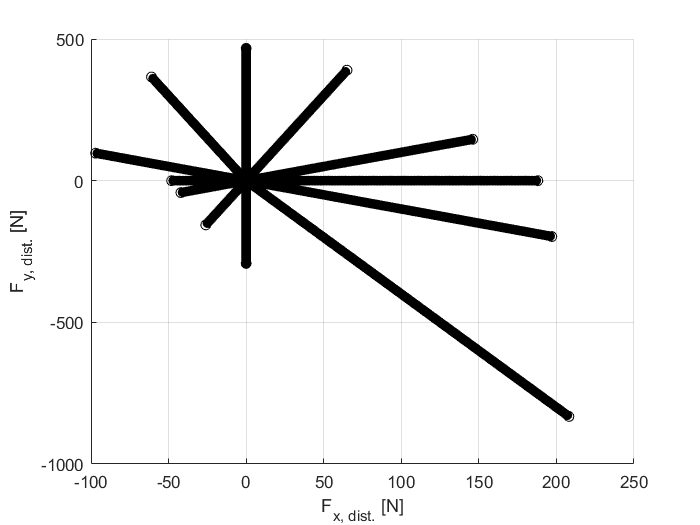

% combine the disturbance test results ([9.7 s, 9.8 s])
distTestResults(1) = load('disturbance test results\distTestResults2022-01-05-21-19.mat');
distTestResults(2) = load('disturbance test results\distTestResults2022-01-05-22-35.mat');
distTestResults(3) = load('disturbance test results\distTestResults2022-01-06-15-01.mat');
distTestResults(4) = load('disturbance test results\distTestResults2022-01-06-18-39.mat');
distTestResults(5) = load('disturbance test results\distTestResults2022-01-07-04-49.mat');
distTestResults(6) = load('disturbance test results\distTestResults2022-01-07-22-22.mat');
distTestResults(7) = load('disturbance test results\distTestResults2022-01-08-00-32.mat');
distTestResults(8) = load('disturbance test results\distTestResults2022-01-08-05-17.mat');
distTestResults(9) = load('disturbance test results\distTestResults2022-01-08-12-15.mat');
distTestResults(10) = load('disturbance test results\distTestResults2022-01-08-16-14.mat');
distTestResults(11) = load('disturbance test results\distTestResults2022-01-08-17-55.mat');
distTestResults(12) = load('disturbance test results\distTestResults2022-01-08-21-09.mat');
distTestResults(13) = load('disturbance test results\distTestResults2022-01-09-02-24.mat');


figure()
hold on
for k = 1:length(distTestResults)
    
    pass = distTestResults(k).distResults.pass;
    for i = 1:length(pass(:,1))
        if pass(i,1) == 1
            F_x_dist = pass(i,2);
            F_y_dist = pass(i,3);
            plot(F_x_dist, F_y_dist, 'k.', 'MarkerSize', 20)
            
        elseif pass(i,1) == 0
            F_x_dist = pass(i,2);
            F_y_dist = pass(i,3);
            plot(F_x_dist, F_y_dist, 'ko', 'MarkerSize', 6)
        end
        
    end
end

grid on
xlabel('F_{x, dist.} [N]')
ylabel('F_{y, dist.} [N]')

for i=1:length(pass)
    rec_pass(i,:) = [pass(i), F_dist_x(i), 0];
end

Index exceeds the number of array elements (1).